# STEP 4 — VISUAL-INERTIAL STATE ESTIMATION WITH AN ERROR-STATE EKF

We use inertial propagation from the accelerometer and gyroscope and correct that propagated state using camera position and attitude measurements. 

The filter is written as an error-state EKF, so the nominal attitude remains on SO(3) while small attitude errors are represented by a three-dimensional rotation vector.

## 1. Load the measurements and define the estimation problem

The estimator begins by loading the data generated by Step 3 and checking that every required measurement exists. The state that we want to estimate contains position, velocity, attitude and the two IMU biases.


$$\hat{\mathbf{x}}=\{\hat{\mathbf{p}},\hat{\mathbf{v}},\hat R,\hat{\mathbf b}_a,\hat{\mathbf b}_g\}$$


The nominal state contains 3 position variables, 3 velocity variables, 3 attitude-error variables, 3 accelerometer-bias variables and 3 gyroscope-bias variables. Thus the error state has dimension 15.


$$\delta\mathbf{x}=\left[\matrix{\delta\mathbf{p} \cr \delta\mathbf{v} \cr \delta\mathbf{\theta} \cr \delta\mathbf{b}_a \cr \delta\mathbf{b}_g}\right]\in\mathbb{R}^{15}$$


load('drone_toy_model.mat');
whos

  Name                             Size                Bytes  Class     Attributes

  R_camera                         3x3x1001            72072  double              
  R_relative                       3x3                    72  double              
  R_true                           3x3x1001            72072  double              
  Rk                               3x3                    72  double              
  Rx                               3x3                    72  double              
  Ry                               3x3                    72  double              
  Rz                               3x3                    72  double              
  T                                1x1                     8  double              
  U                                3x3                    72  double              
  V                                3x3                    72  double              
  a0                               1x3                    24  double              
  a

The second loading block performs the actual input validation for the estimator. It checks that the trajectory, true motion, camera measurements and IMU measurements generated in Step 3 are available before the filter begins.


$$\mathcal Z_k=\{\mathbf p_{camera,k},R_{camera,k},\mathbf a_{imu,k},\mathbf{\omega}_{imu,k}\}$$


clc;
clear;
close all;

load('drone_toy_model.mat');

requiredVariables = {
    't'
    'dt'
    'pd'
    'vd'
    'ad'
    'p_true'
    'v_true'
    'a_true'
    'p_camera'
    'a_imu'
    'omega_imu'
    'R_camera'
};

for i = 1:length(requiredVariables)

    if ~exist(requiredVariables{i},'var')

        error(['Missing variable: ', ...
               requiredVariables{i}, ...
               '. Update Step 3 so it saves this variable ', ...
               'to drone_toy_model.mat.']);

    end

end

numSamples = length(t);

g = [0; 0; -9.81];

## 2. Construct the attitude used for initialization

The filter needs an initial attitude estimate. The same simple yaw, pitch and roll construction used in Step 3 is repeated here so that an initial rotation matrix can be formed from the trajectory data. The estimator itself will subsequently use the camera attitude and IMU gyroscope to evolve this state.


$$R=R_z(\psi)R_y(\theta)R_x(\phi)$$


The angles are computed from the horizontal velocity and horizontal acceleration. This is an initialization convenience for the toy model, not a general-purpose attitude estimator.


for k = 1:numSamples

    %% Desired yaw

    if norm(v_true(k,1:2)) > 1e-4

        yaw = ...
            atan2(v_true(k,2), ...
                  v_true(k,1));

    else

        yaw = 0;

    end

    %% Approximate pitch and roll

    pitch = ...
        atan2(a_true(k,1),9.81);

    roll = ...
        -atan2(a_true(k,2),9.81);

    %% Rotation about X

    Rx = [
        1 0 0;
        0 cos(roll) -sin(roll);
        0 sin(roll) cos(roll)
    ];

    %% Rotation about Y

    Ry = [
        cos(pitch) 0 sin(pitch);
        0 1 0;
        -sin(pitch) 0 cos(pitch)
    ];

    %% Rotation about Z

    Rz = [
        cos(yaw) -sin(yaw) 0;
        sin(yaw) cos(yaw) 0;
        0 0 1
    ];

end
sigma_visual_position = 0.05;

sigma_visual_angle = deg2rad(1.0);

## 3. Initialize the nominal state

At the first sample, the camera provides the initial position and attitude measurement, so these are used to initialize p_est and R_est. The initial velocity is set to zero, and both sensor bias estimates start at zero.


$$\hat{\mathbf p}_0=\mathbf p_{camera,0},\qquad \hat R_0=R_{camera,0},\qquad \hat{\mathbf v}_0=\mathbf0$$


ba_est and bg_est are the filter’s estimates of the accelerometer and gyroscope biases. Starting them at zero means that the filter must learn any actual bias from the subsequent measurements.

p_est =p_camera(1,:)';
v_est = zeros(3,1);

R_est =R_camera(:,:,1);

ba_est = zeros(3,1);
bg_est = zeros(3,1);

## 4. Represent uncertainty in the initial state and measurements

An estimate without uncertainty is incomplete for a Kalman filter. P_cov is the covariance of the 15-dimensional error state. Large diagonal entries would indicate greater initial uncertainty; here a common initial value is used for simplicity.


$$P=E[\delta\mathbf{x}\delta\mathbf{x}^T]$$


The camera measurement covariance R_visual is six-dimensional because each visual update contains three position components and three attitude-error components.


$$R_{visual}=\mathrm{diag}(\sigma_p^2,\sigma_p^2,\sigma_p^2,\sigma_R^2,\sigma_R^2,\sigma_R^2)$$


sigma_visual_position is the standard deviation assigned to the camera position measurement and sigma_visual_angle is the standard deviation assigned to the camera attitude measurement.

P_cov = ...
    eye(15) * 0.01;

R_visual = diag([
    sigma_visual_position^2
    sigma_visual_position^2
    sigma_visual_position^2
    sigma_visual_angle^2
    sigma_visual_angle^2
    sigma_visual_angle^2
]);


## 5. Model process uncertainty

Q represents uncertainty in the continuous model and unmodelled disturbances. The blocks correspond to position, velocity, attitude error, accelerometer bias and gyroscope bias in the 15-dimensional error state.


$$P_{k+1}=F_kP_kF_k^T+Q$$


The numerical values in Q are tuning assumptions for this toy model. They do not come from the trajectory itself; they describe how much process uncertainty we allow the filter to accumulate between measurements.

Q = zeros(15);

Q(1:3,1:3) = ...
    1e-5 * eye(3);

Q(4:6,4:6) = ...
    1e-3 * eye(3);

Q(7:9,7:9) = ...
    1e-4 * eye(3);

Q(10:12,10:12) = ...
    1e-6 * eye(3);

Q(13:15,13:15) = ...
    1e-6 * eye(3);

## 6. Allocate storage for the estimated history

The filter updates one state at every time sample. The history arrays store the estimated position, velocity, rotation, angular velocity and both bias estimates so that the final result can be compared with ground truth.


$$\hat{\mathbf p}_k,\;\hat{\mathbf v}_k,\;\hat R_k,\;\hat{\mathbf\omega}_k,\;\hat{\mathbf b}_{a,k},\;\hat{\mathbf b}_{g,k}$$



p_est_history = zeros(numSamples,3);

v_est_history =zeros(numSamples,3);

R_est_history = zeros(3,3,numSamples);

omega_est_history=zeros(numSamples,3);

ba_est_history =zeros(numSamples,3);

bg_est_history =zeros(numSamples,3);

## 7. Start the EKF time loop and remove estimated bias

At each sample the raw IMU measurements are corrected using the current bias estimates. This is the first step in using the sensor measurements to propagate the nominal state.


$$\mathbf a_c=\mathbf a_{imu}-\hat{\mathbf b}_a,\qquad \mathbf{\omega}_c=\mathbf{\omega}_{imu}-\hat{\mathbf b}_g$$


The corrected accelerometer is still expressed in the body frame, so it must be rotated into the inertial frame before it can be used for position and velocity propagation.


for k = 1:numSamples
    a_corrected = a_imu(k,:)' - ba_est;

    omega_corrected = omega_imu(k,:)' - bg_est;

    if k > 1

        %% Position

## 8. Propagate position

Assuming the corrected acceleration is approximately constant over one sample interval, the standard constant-acceleration update is used for position.


$$\hat{\mathbf p}_{k+1}=\hat{\mathbf p}_k+\hat{\mathbf v}_k\Delta t+\frac12\left(\hat R_k\mathbf a_c+\mathbf g\right)\Delta t^2$$


Here p_est is the estimated inertial position, v_est is estimated inertial velocity, R_est converts body acceleration to inertial coordinates, a_corrected is the bias-corrected accelerometer reading, g is gravity and dt is the sample interval.

        p_est = p_est + v_est*dt + 0.5 * (R_est*a_corrected + g) * dt^2;

        %% Velocity

## 9. Propagate velocity

Velocity follows from integrating inertial acceleration over one sample.


$$\hat{\mathbf v}_{k+1}=\hat{\mathbf v}_k+\left(\hat R_k\mathbf a_c+\mathbf g\right)\Delta t$$


The same acceleration used in the position equation appears here. The difference is that velocity uses one integration of acceleration, while position uses the first two terms of the constant-acceleration expression.

        v_est = v_est + (R_est*a_corrected + g)*dt;

        %% Orientation
        %
        % R(k+1) =
        % R(k) Exp([omega]x dt)
        %

## 10. Propagate attitude on SO(3)

Attitude cannot be propagated by adding angular velocity directly to the nine elements of R. Instead, angular velocity is converted into a small rotation and composed with the current rotation. This is the matrix form of the exponential-map update.


$$\hat R_{k+1}=\hat R_k\exp([\mathbf{\omega}_c\Delta t]_\times)$$


Floating-point integration can introduce a small numerical violation of R^T R = I or det(R)=1. The SVD projection finds the nearest orthogonal matrix in the numerical sense and then the determinant check ensures a proper rotation rather than a reflection.


$$R^TR=I,\qquad\det(R)=1$$


The matrices U and V come from R = U\Sigma V^T. Replacing R by UV^T removes the numerical scaling/shearing component. If the determinant is negative, the third singular vector is flipped before recomputing the projection.

        R_est = R_est * expm(skew(omega_corrected*dt));

        %% Force R back onto SO(3)

        [U,~,V] = svd(R_est);

        R_est = U*V';

        if det(R_est) < 0

            U(:,3) = -U(:,3);

            R_est = U*V';

        end

    end

## 12. Construct the 15-dimensional error-state transition matrix

The EKF does not propagate a full 15-dimensional nonlinear state directly. Instead, it linearizes how a small error changes from one sample to the next. The resulting matrix F is the discrete error-state transition matrix.


$$\delta\mathbf x_{k+1}=F_k\delta\mathbf x_k+\mathbf w_k$$


The first block captures the fact that a position error changes when there is a velocity error.


$$\delta\mathbf p_{k+1}\approx\delta\mathbf p_k+\delta\mathbf v_k\Delta t$$


    %% ====================================================
    % C. Error-state transition matrix
    % ====================================================

    F = eye(15);

    %% Position error depends on velocity error

    F(1:3,4:6) = eye(3)*dt;

## 13. Linearize velocity and attitude errors

The velocity error depends on attitude error because an attitude error changes the direction in which the measured specific force is rotated. It also depends directly on accelerometer-bias error.


$$F_{v\theta}=-R[\mathbf a_c]_\times\Delta t,\qquad F_{vb_a}=-R\Delta t$$


The attitude-error block accounts for the local rotational dynamics. For a right attitude error, the linearized propagation uses the negative angular-velocity skew matrix.


$$F_{\theta\theta}=\exp(-[\mathbf{\omega}_c\Delta t]_\times),\qquad F_{\theta b_g}=-I\Delta t$$


These terms tell the filter how uncertainty in attitude and sensor bias will influence future estimates.

    %% Velocity error due to attitude error

    F(4:6,7:9) = -R_est * skew(a_corrected) * dt;

    %% Velocity error due to accelerometer bias

    F(4:6,10:12) = -R_est * dt;

    %% Attitude error propagation

    F(7:9,7:9) = ...
        expm(-skew(omega_corrected*dt));

    %% Attitude error due to gyro bias

    F(7:9,13:15) = ...
        -eye(3)*dt;

## 14. Propagate covariance

Once F has been constructed, the uncertainty is propagated through the linearized model.


$$P_{k+1}^- = F_kP_k^+F_k^T+Q$$


P_cov is the current covariance, F is the transition matrix and Q is the process-noise covariance. The superscripts minus and plus distinguish the predicted covariance from the covariance after the measurement correction.

    %% ====================================================
    % D. Covariance propagation
    % ====================================================

    P_cov = ...
        F * P_cov * F' + Q;

## 15. Form the camera position innovation

A measurement update starts by comparing what the camera says with what the current estimate predicts. The difference is called the innovation or residual.


$$\mathbf r_p=\mathbf z_p-\hat{\mathbf p}$$


Here z_position is p_camera, the measured position, and p_est is the predicted position. A positive residual means the camera places the vehicle in the positive direction relative to the current estimate.

    %% ====================================================
    % E. Visual position innovation
    % ====================================================

    z_position = ...
        p_camera(k,:)';

    position_innovation = ...
        z_position - p_est;

## 16. Form the camera attitude innovation

Attitude residuals cannot be computed by subtracting the nine elements of two rotation matrices. Instead, we form the relative rotation from the estimated attitude to the measured attitude and use the SO(3) logarithm.


$$R_{err}=\hat R^TR_{camera},\qquad\delta\mathbf{\theta}=\log(R_{err})$$


The resulting three-vector delta_theta is the small rotation that would move the estimated attitude toward the camera attitude. This is the right attitude-error convention used in the code.

    %% ====================================================
    % F. Visual attitude innovation
    %
    % Right attitude error:
    %
    % delta_theta =
    % Log( R_est' R_visual )
    % ====================================================

    R_visual_k = ...
        R_camera(:,:,k);

    R_error = ...
        R_est' * R_visual_k;

    delta_theta = ...
        logSO3(R_error);

## 17. Combine the visual residuals

The camera supplies two different kinds of information: three position components and three attitude-error components. They are stacked into one six-dimensional innovation vector.


$$\mathbf r=\left[\matrix{\mathbf r_p \cr delta\mathbf{\theta}}\right]\in\mathbb R^6$$


The order of this vector must agree with the order used by H and R_visual.

    %% ====================================================
    % G. Combined visual innovation
    % ====================================================

    innovation = [
        position_innovation;
        delta_theta
    ];

## 18. Build the measurement matrix

The measurement matrix H tells the EKF which components of the error state are directly observed by the camera. Position observes delta_p and attitude observes delta_theta; velocity and the two biases are not directly measured in this update.


$$H=\left[\matrix{ I & 0 & 0 & 0 & 0 \cr 0 & 0 & I & 0 & 0} \right]$$


H is therefore 6-by-15: six measured quantities and fifteen error-state variables.

    %% ====================================================
    % H. Measurement matrix
    %
    % Position measurement observes delta_p.
    %
    % Attitude measurement observes delta_theta.
    % ====================================================

    H = zeros(6,15);

    H(1:3,1:3) = ...
        eye(3);

    H(4:6,7:9) = ...
        eye(3);

## 19. Compute innovation covariance

The innovation itself is uncertain because both the predicted state and the camera measurement are uncertain. The covariance of that residual is


$$S=HP^-H^T+R$$


Here S is the six-by-six innovation covariance, P^- is the predicted state covariance, and R is R_visual, the camera measurement covariance. A larger measurement uncertainty produces a larger R and makes the filter trust the camera less.

    %% ====================================================
    % I. Innovation covariance
    % ====================================================

    S = ...
        H * P_cov * H' + R_visual;

## 20. Compute the Kalman gain

The Kalman gain determines how strongly the innovation should change the state estimate.


$$K=P^-H^TS^{-1}$$


P_cov contains the predicted uncertainty, H maps state errors into measurement space, and S describes the uncertainty of the innovation. In MATLAB the right-division form avoids explicitly computing the inverse of S.

    %% ====================================================
    % J. Kalman gain
    % ====================================================

    K = ...
        P_cov * H' / S;

## 21. Estimate and inject the error state

The estimated 15-dimensional correction is obtained by multiplying the Kalman gain by the innovation.


$$\delta\hat{\mathbf x}=K\mathbf r$$


The position and velocity corrections are added directly. The attitude correction is different: a three-vector rotation error is converted into a rotation matrix and multiplied onto R_est. The accelerometer and gyroscope bias estimates are updated additively.


$$\hat R^+ = \hat R^-\exp([\delta\mathbf{\theta}]_\times)$$


After injection, the attitude is projected back onto SO(3). The Joseph covariance update is then used because it is numerically safer than the simplified (I-KH)P expression.


$$P^+=(I-KH)P^-(I-KH)^T+KRK^T$$


Finally, the corrected state is stored for later comparison with ground truth.

    %% ====================================================
    % K. Estimate error state
    % ====================================================

    delta_x = ...
        K * innovation;

    %% ====================================================
    % L. Inject error into nominal state
    % ====================================================

    %% Position

    p_est = ...
        p_est + delta_x(1:3);

    %% Velocity

    v_est = ...
        v_est + delta_x(4:6);

    %% Attitude

    R_est = ...
        R_est * ...
        expm(skew(delta_x(7:9)));

    %% Accelerometer bias

    ba_est = ...
        ba_est + delta_x(10:12);

    %% Gyroscope bias

    bg_est = ...
        bg_est + delta_x(13:15);

    %% Ensure attitude remains in SO(3)

    [U,~,V] = svd(R_est);

    R_est = U*V';

    if det(R_est) < 0

        U(:,3) = -U(:,3);

        R_est = U*V';

    end

    %% ====================================================
    % M. Joseph-form covariance update
    %
    % More numerically stable than:
    %
    % P = (I-KH)P
    % ====================================================

    I_KH = ...
        eye(15) - K*H;

    P_cov = ...
        I_KH * P_cov * I_KH' ...
        + K * R_visual * K';

    %% ====================================================
    % N. Store estimated state
    % ====================================================

    p_est_history(k,:) = ...
        p_est';

    v_est_history(k,:) = ...
        v_est';

    R_est_history(:,:,k) = ...
        R_est;

    omega_est_history(k,:) = ...
        omega_corrected';

    ba_est_history(k,:) = ...
        ba_est';

    bg_est_history(k,:) = ...
        bg_est';

end

## 22. Compute position and velocity estimation errors

Once the filter has processed the complete measurement sequence, we compare its estimates with the true simulated motion. The error is defined as estimate minus truth.


$$\mathbf e_p=\hat{\mathbf p}-\mathbf p_{true},\qquad \mathbf e_v=\hat{\mathbf v}-\mathbf v_{true}$$


The RMSE is computed separately for x, y and z so that an error in one direction does not hide an error in another.


$$RMSE_x=\sqrt{\frac1N\sum_{k=1}^N e_{x,k}^2}$$



%% ========================================================
% 12. Estimation errors
% =========================================================

position_error = ...
    p_est_history - p_true;

velocity_error = ...
    v_est_history - v_true;

position_RMSE = ...
    sqrt(mean(position_error.^2,1));

velocity_RMSE = ...
    sqrt(mean(velocity_error.^2,1));

## 23. Compute attitude estimation error

The attitude error is again measured on SO(3), not by subtracting matrix elements. The relative rotation from the true attitude to the estimated attitude is mapped into a rotation vector.


$$R_{err,k}=R_{true,k}^T\hat R_k,\qquad\mathbf{\theta}_{err,k}=\log(R_{err,k})$$


Its norm is the magnitude of the attitude error in radians. The final RMSE is the root mean square of this scalar angle error.


$$RMSE_R=\sqrt{\frac1N\sum_{k=1}^N\|\mathbf{\theta}_{err,k}\|^2}$$



%% ========================================================
% 13. Attitude estimation error
% =========================================================

attitude_error = ...
    zeros(numSamples,1);

for k = 1:numSamples

    R_error = ...
        R_true(:,:,k)' * ...
        R_est_history(:,:,k);

    theta_error = ...
        logSO3(R_error);

    attitude_error(k) = ...
        norm(theta_error);

end

attitude_RMSE = ...
    sqrt(mean(attitude_error.^2));

## 24. Check that the estimated rotations remain valid

A rotation matrix must remain orthogonal and have determinant +1. These two scalar checks quantify how closely the estimated matrices satisfy the mathematical definition of SO(3).


$$e_{orth}=\|R^TR-I\|_F,\qquad e_{det}=|\det(R)-1|$$


The Frobenius norm is used for the orthogonality error. Both values should remain very close to zero if the projection and attitude update are behaving correctly.


%% ========================================================
% 14. SO(3) validity checks
% =========================================================

rotation_orthogonality_error = ...
    zeros(numSamples,1);

rotation_determinant_error = ...
    zeros(numSamples,1);

for k = 1:numSamples

    Rk = ...
        R_est_history(:,:,k);

    rotation_orthogonality_error(k) = ...
        norm(Rk'*Rk - eye(3),'fro');

    rotation_determinant_error(k) = ...
        abs(det(Rk)-1);

end

## 25. Visualize the position estimate

The first plot compares the true x-position, the noisy visual measurement and the EKF estimate. The camera signal is noisy because of the measurement model from Step 3, while the EKF combines that measurement with inertial propagation.


$$e_x(t)=\hat x(t)-x_{true}(t)$$


The purpose of this plot is therefore not just to show a curve; it shows the filtering effect: the estimate should be less erratic than the raw measurement while remaining close to the true trajectory.

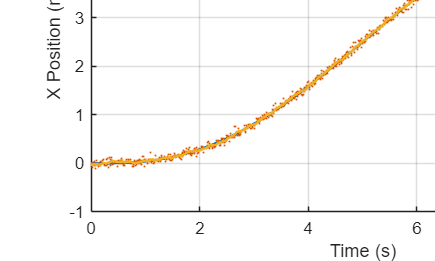


%% ========================================================
% 15. Plot X position
% =========================================================

figure;

plot(t,p_true(:,1), ...
     'LineWidth',1.5);

hold on;

plot(t,p_camera(:,1), ...
     '.', ...
     'MarkerSize',3);

plot(t,p_est_history(:,1), ...
     'LineWidth',1.5);

xlabel('Time (s)');
ylabel('X Position (m)');

title('VIO Position Estimation');

legend( ...
    'True', ...
    'Visual Measurement', ...
    'VIO Estimate');

grid on;

## 26. Visualize the estimated 3D trajectory

The three-dimensional plot checks whether the complete estimated path follows the actual path. Agreement in one coordinate alone is not sufficient because the vehicle moves in three dimensions.


$$\hat{\mathbf p}(t)\approx\mathbf p_{true}(t)$$


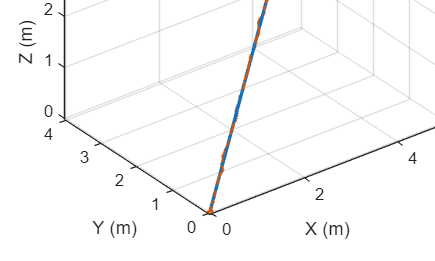


%% ========================================================
% 16. Plot 3D trajectory
% =========================================================

figure;

plot3( ...
    p_true(:,1), ...
    p_true(:,2), ...
    p_true(:,3), ...
    'LineWidth',2);

hold on;

plot3( ...
    p_est_history(:,1), ...
    p_est_history(:,2), ...
    p_est_history(:,3), ...
    'LineWidth',1.5);

grid on;
axis equal;

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

title('True vs VIO Estimated Trajectory');

legend( ...
    'True trajectory', ...
    'VIO estimate');

## 27. Plot position error

The position-error plot shows each component of the estimation error as a function of time. It is useful for identifying a systematic offset, transient response or drift that a single RMSE number would hide.


$$\mathbf e_p(t)=\hat{\mathbf p}(t)-\mathbf p_{true}(t)$$


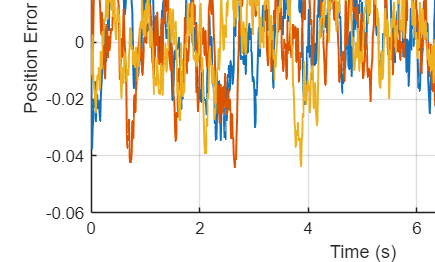


%% ========================================================
% 17. Plot position error
% =========================================================

figure;

plot( ...
    t, ...
    position_error(:,1), ...
    'LineWidth',1.2);

hold on;

plot( ...
    t, ...
    position_error(:,2), ...
    'LineWidth',1.2);

plot( ...
    t, ...
    position_error(:,3), ...
    'LineWidth',1.2);

xlabel('Time (s)');
ylabel('Position Error (m)');

title('VIO Position Estimation Error');

legend('X','Y','Z');

grid on;

## 28. Plot velocity error

The same analysis is applied to velocity. Since velocity is obtained by integrating the IMU acceleration, velocity error is an important indicator of whether the inertial propagation and bias estimation are working together.


$$\mathbf e_v(t)=\hat{\mathbf v}(t)-\mathbf v_{true}(t)$$



%% ========================================================
% 18. Plot velocity error
% =========================================================

figure;

plot( ...
    t, ...
    velocity_error(:,1), ...
    'LineWidth',1.2);

hold on;

plot( ...
    t, ...
    velocity_error(:,2), ...
    'LineWidth',1.2);

plot( ...
    t, ...
    velocity_error(:,3), ...
    'LineWidth',1.2);

xlabel('Time (s)');
ylabel('Velocity Error (m/s)');

title('VIO Velocity Estimation Error');

legend('X','Y','Z');

grid on;

## 29. Plot attitude error

The attitude error is plotted in degrees for easier interpretation. Internally the logarithm map returns radians, so rad2deg is used only for display.


$$\theta_{err,deg}=\frac{180}{\pi}\|\log(R_{true}^T\hat R)\|$$


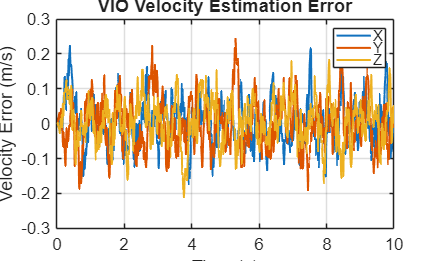

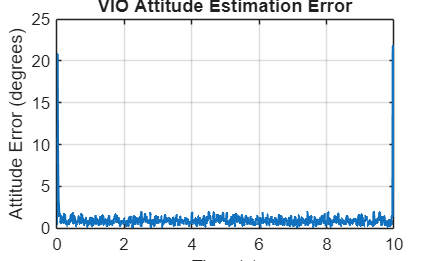

%% ========================================================
% 19. Plot attitude error
% =========================================================

figure;

plot( ...
    t, ...
    rad2deg(attitude_error), ...
    'LineWidth',1.5);

xlabel('Time (s)');
ylabel('Attitude Error (degrees)');

title('VIO Attitude Estimation Error');

grid on;

## 30. Display and save the estimation results

The printed quantities summarize the numerical quality of the estimator: position RMSE, velocity RMSE, attitude RMSE, the final bias estimates and the maximum SO(3) validity errors. These values are diagnostic quantities, not new states.


$$RMSE=\sqrt{\frac1N\sum_{k=1}^N e_k^2}$$


The same block saves the complete estimation history and the sensor statistics so that Step 5 can use the estimated state rather than the true state. This is the critical interface between estimation and control.


%% ========================================================
% 20. Display results
% =========================================================

fprintf('\n');
fprintf('========================================\n');

fprintf('VISUAL-INERTIAL ESTIMATION RESULTS\n');

VISUAL-INERTIAL ESTIMATION RESULTS


fprintf('========================================\n');

fprintf('\nPosition RMSE:\n');



Position RMSE:


fprintf('X = %.4f m\n', ...
    position_RMSE(1));

X = 0.0149 m



fprintf('Y = %.4f m\n', ...
    position_RMSE(2));

fprintf('Z = %.4f m\n', ...

Y = 0.0170 m


    position_RMSE(3));

Z = 0.0154 m



fprintf('\nVelocity RMSE:\n');

fprintf('X = %.4f m/s\n', ...


Velocity RMSE:


    velocity_RMSE(1));

X = 0.0639 m/s



fprintf('Y = %.4f m/s\n', ...
    velocity_RMSE(2));

Y = 0.0712 m/s



fprintf('Z = %.4f m/s\n', ...
    velocity_RMSE(3));

Z = 0.0632 m/s



fprintf('\nAttitude RMSE = %.4f degrees\n', ...
    rad2deg(attitude_RMSE));


Attitude RMSE = 1.4429 degrees



fprintf('\nFinal accelerometer bias estimate:\n');


Final accelerometer bias estimate:



disp(ba_est');

    0.0074   -0.0035    0.0173




fprintf('Final gyroscope bias estimate:\n');

Final gyroscope bias estimate:



disp(bg_est');

fprintf('\nSO(3) validity:\n');


    0.0073   -0.0025   -0.0126




SO(3) validity:


fprintf( ...
    'Maximum orthogonality error = %.4e\n', ...
    max(rotation_orthogonality_error));

Maximum orthogonality error = 1.4115e-15



fprintf( ...
    'Maximum determinant error = %.4e\n', ...
    max(rotation_determinant_error));

Maximum determinant error = 8.8818e-16



%% ========================================================
% 21. SAVE OUTPUTS FOR STEP 5
% =========================================================

save('drone_toy_model.mat', ...
    'p0', ...
    'pf', ...
    'v0', ...
    'vf', ...
    'a0', ...
    'af', ...
    'T', ...
     't', ...
     'dt', ...
     'pd', ...
     'vd', ...
     'ad', ...
     'p_true', ...
     'v_true', ...
     'a_true', ...
     'p_camera', ...
     'R_camera',...
     'R_true',...
     'a_imu', ...
     'omega_true', ...
     'omega_imu', ...
     'p_est_history', ...
     'v_est_history', ...
     'R_est_history', ...
     'omega_est_history', ...
     'ba_est_history', ...
     'bg_est_history', ...
     'position_RMSE', ...
     'velocity_RMSE', ...
     'attitude_RMSE', ...
     'sigma_position', ...
    'sigma_camera_angle', ...
    'sigma_acceleration', ...
    'sigma_gyro', ...
    'accel_bias', ...
    'gyro_bias');

fprintf('\nStep 4 results saved to drone_toy_model.mat\n');


Step 4 results saved to drone_toy_model.mat


## 31. Local SO(3) functions

The local functions implement the two geometric operations used throughout the EKF. skew(v) constructs the matrix representation of the cross product, while logSO3(R) converts a rotation matrix into its rotation-vector representation.


$$[\mathbf v]_\times\mathbf u=\mathbf v\times\mathbf u$$



$$\log(R)=\frac{\theta}{2\sin\theta}\left[\matrix{R_{32}-R_{23} \cr R_{13}-R_{31} \cr R_{21}-R_{12}}\right],\quad \theta=\cos^{-1}\left(\frac{\mathrm
{tr}(R)-1}{2}\right)$$


The numerical safeguards in the function prevent invalid acos arguments and avoid division by a very small sin(theta) for nearly identity rotations.


%% ========================================================
% LOCAL FUNCTIONS
% =========================================================

function S = skew(v)

    S = [
         0    -v(3)  v(2);
         v(3)  0    -v(1);
        -v(2) v(1)   0
    ];

end


function v = logSO3(R)

    %% Numerical protection

    cos_theta = ...
        (trace(R)-1)/2;

    cos_theta = ...
        max(-1,min(1,cos_theta));

    theta = ...
        acos(cos_theta);

    if theta < 1e-8

        v = zeros(3,1);

    else

        v = ...
            theta/(2*sin(theta)) * ...
            [
                R(3,2)-R(2,3);
                R(1,3)-R(3,1);
                R(2,1)-R(1,2)
            ];

    end

end

## 32. Inspect the saved camera attitude

This block opens the MAT-file and displays R_camera. It is a direct inspection of the stored camera attitude sequence. No estimation is performed here; the purpose is to verify that the synthetic attitude measurements were saved in the expected 3-by-3-by-N form.


$$R_{camera}(:,:,k)\in SO(3)$$


open("drone_toy_model.mat")

ans = struct with fields:
              R_camera: [3×3×1001 double]
         R_est_history: [3×3×1001 double]
                R_true: [3×3×1001 double]
                     T: 10
                    a0: [0 0 0]
                 a_imu: [1001×3 double]
                a_true: [1001×3 double]
            accel_bias: [0.0200 -0.0100 0.0300]
                    ad: [1001×3 double]
                    af: [0 0 0]
         attitude_RMSE: 0.0252
        ba_est_history: [1001×3 double]
        bg_est_history: [1001×3 double]
                    dt: 0.0100
             gyro_bias: [0.0050 -0.0030 0.0020]
     omega_est_history: [1001×3 double]
             omega_imu: [1001×3 double]
            omega_true: [1001×3 double]
                    p0: [0 0 0]
              p_camera: [1001×3 double]
         p_est_history: [1001×3 double]
                p_true: [1001×3 double]
                    pd: [1001×3 double]
                    pf: [5 4 3]
         position_RMSE: [0.0149 0.0170 0.0154]
    sigm

R_camera

R_camera = R_camera(:,:,1) =

    0.9998   -0.0131   -0.0121
    0.0127    0.9995   -0.0287
    0.0125    0.0286    0.9995


R_camera(:,:,2) =

    1.0000    0.0084    0.0050
   -0.0084    0.9999    0.0068
   -0.0050   -0.0069    1.0000


R_camera(:,:,3) =

    0.9998   -0.0136   -0.0148
    0.0138    0.9997    0.0189
    0.0145   -0.0191    0.9997


R_camera(:,:,4) =

    0.7725   -0.6350   -0.0005
    0.6350    0.7725   -0.0021
    0.0017    0.0014    1.0000


R_camera(:,:,5) =

    0.7811   -0.6242   -0.0130
    0.6243    0.7807    0.0277
   -0.0071   -0.0297    0.9995


R_camera(:,:,6) =

    0.7838   -0.6209   -0.0063
    0.6208    0.7838   -0.0179
    0.0161    0.0101    0.9998


R_camera(:,:,7) =

    0.7996   -0.6005   -0.0108
    0.6004    0.7996   -0.0080
    0.0135   -0.0001    0.9999


R_camera(:,:,8) =

    0.7787   -0.6274   -0.0009
    0.6273    0.7787   -0.0095
    0.0066    0.0068    1.0000


R_camera(:,:,9) =

    0.7872   -0.6161   -0.0278
    0.6162    0.7876   -0.0

## 33. Confirm the final workspace

The final workspace check reloads the saved data and lists the variables. This makes the data interface explicit before moving to the controller: the next file should receive the desired trajectory from Step 2 and the estimated state from Step 4.

load('drone_toy_model.mat');
whos

  Name                                 Size                 Bytes  Class     Attributes

  F                                   15x15                  1800  double              
  H                                    6x15                   720  double              
  I_KH                                15x15                  1800  double              
  K                                   15x6                    720  double              
  P_cov                               15x15                  1800  double              
  Q                                   15x15                  1800  double              
  R_camera                             3x3x1001             72072  double              
  R_error                              3x3                     72  double              
  R_est                                3x3                     72  double              
  R_est_history                        3x3x1001             72072  double              
  R_true                       